A = [0, 1; 900, 0]

A =      0     1
   900     0


B = [0; -9]

B =      0
    -9


C = [600, 0]

C =    600     0


D = 0

D = 0

Controllo le proprietà di raggiungibilità

CO = ctrb(A, B)

CO =      0    -9
    -9     0


rank(CO)

ans = 2

Assegno al sistema gli autovalori che disidero (-40 e -60)

eig(A)

ans =    30.0000
  -30.0000


new_eig = [-40, -60]

new_eig =    -40   -60


K = place(A, B, new_eig)

K =  -366.6667  -11.1111


A_ = A-B*K

A_ = 	1.0e+03 *

         0    0.0010
   -2.4000   -0.1000


eig(A_)

ans =   -40.0000
  -60.0000


Retroazione degli stati

C_ = C-D*K

C_ =    600     0


alfa = 1;
B_ = alfa*B

B_ =      0
    -9


D_ = alfa*D

D_ = 0

sys = ss(A_, B_, C_, D_)


sys =
 
  A = 
          x1     x2
   x1      0      1
   x2  -2400   -100
 
  B = 
       u1
   x1   0
   x2  -9
 
  C = 
        x1   x2
   y1  600    0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Risposta sistema retroazionato ad ingresso a onda quadra 0.5Hz, ampiezza 2

Posto alfa = -1

t = 0:0.01:10;
r = 2*sign(sin(2*pi*0.5*t));
alfa = -1;

x_0 1

x_0 = [0; 0]

x_0 =      0
     0


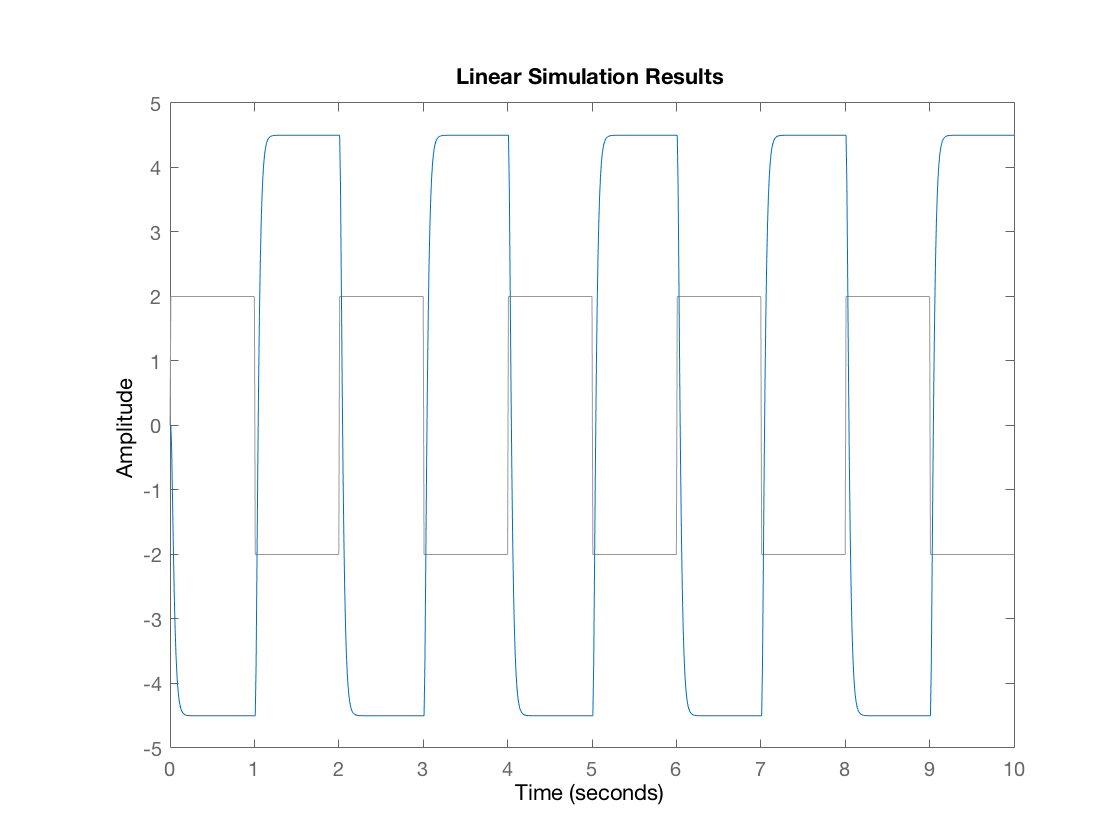

lsim(sys, r, t, x_0)

x_0 2

x_0 = [0.01; 0]

x_0 =     0.0100
         0


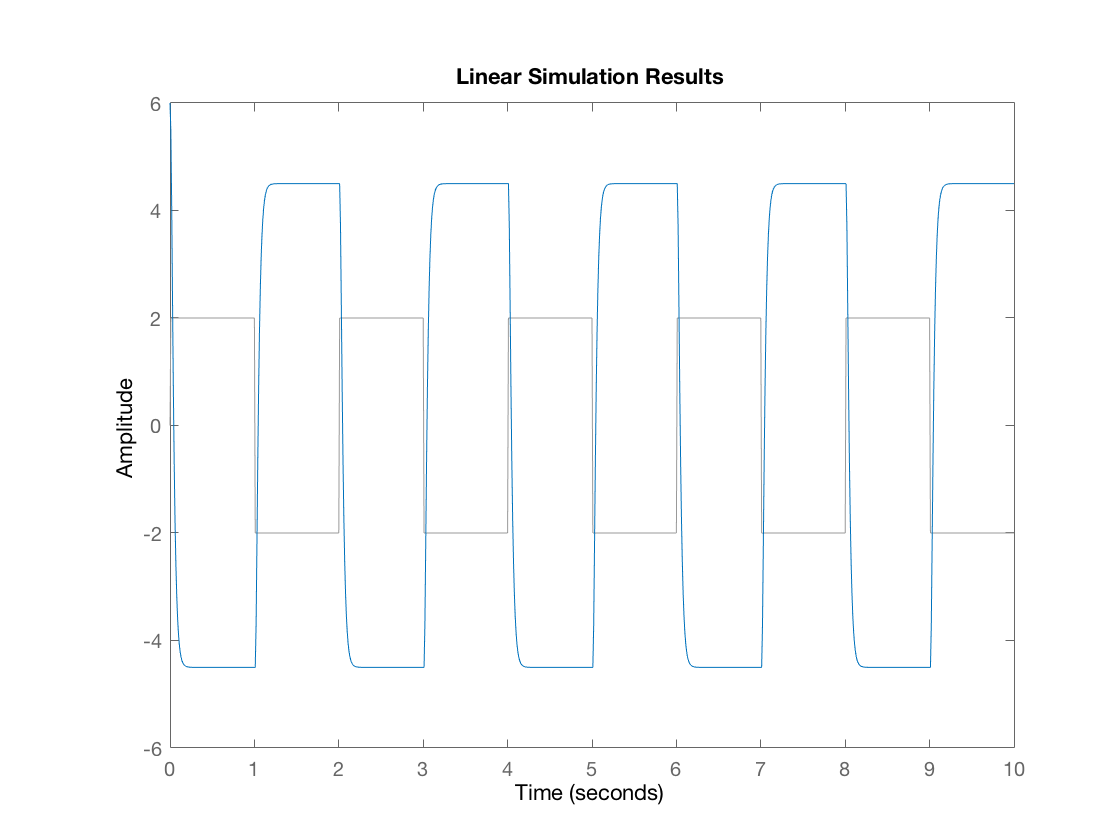

lsim(sys, r, t, x_0)

x_0 3

x_0 = [-0.01; 0]

x_0 =    -0.0100
         0


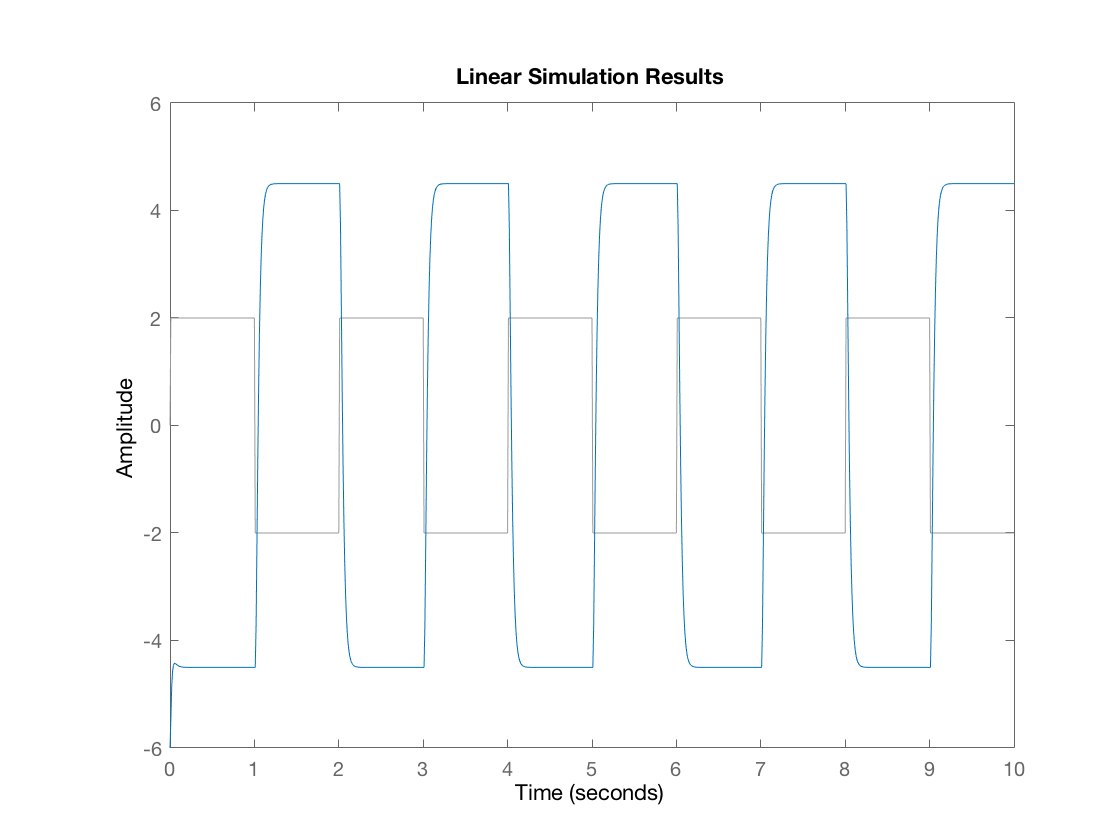

lsim(sys, r, t, x_0)